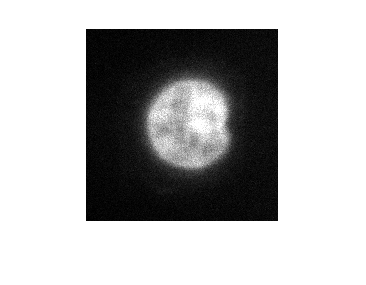

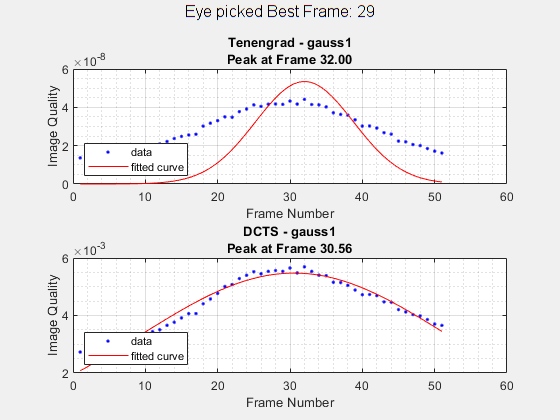

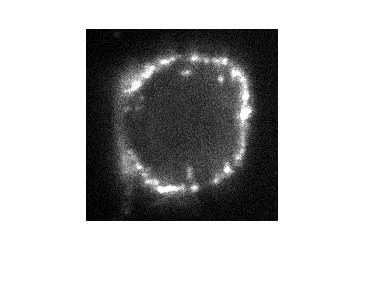

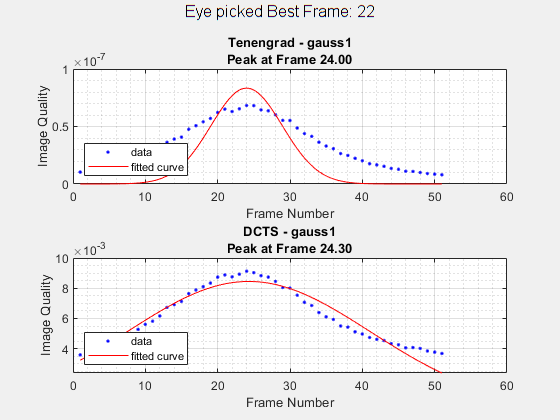

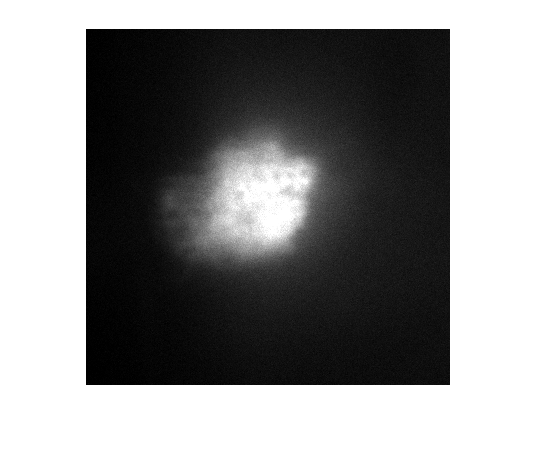

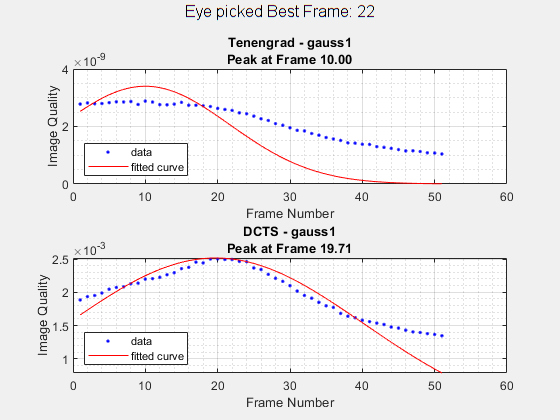

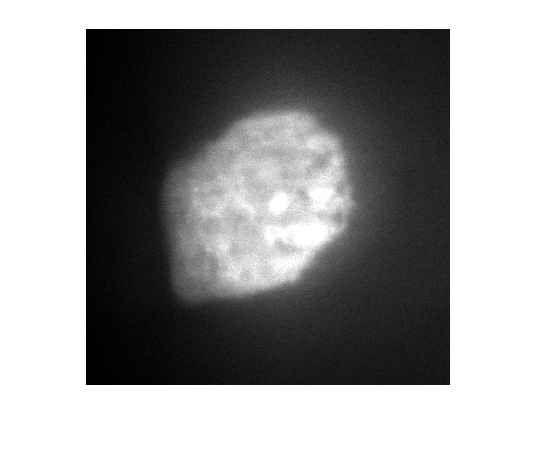

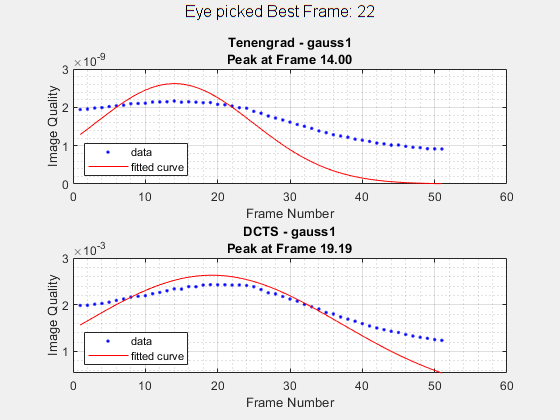

files = {'X:/volume_scan/23-Apr-2018/nucleus_psf_488.tif'...
         ,'X:/volume_scan/23-Apr-2018/membrane_psf_561.tif' ...
         ,'X:/volume_scan/04-May-2018/membrane_psf_561_endpoint.tif' ...
         ,'X:/volume_scan/04-May-2018/membrane_psf_561_tilted_ls.tif' ...
         ,'X:/volume_scan/04-May-2018/membrane_psf_561_0.387_4.55.tif'};
eye_pick_frame = [29, 22, 22, 22, 21];

for i = 1:numel(files)
    figure
    imshow(imadjust(imread(files{i}, eye_pick_frame(i))));
    autopilot(files{i}, eye_pick_frame(i));
end


% AutoPiolot tenengrad steps:
% 1. Subsample the image with PSF. For example, all values from a 3x3 PSF are added to a single point.
% 2. Nomalize the subsampled image with L1 norm.
% 3. Convolve the subsampled image with a sobel kernerl.
% Note: The final tenengrad score was the raw score divided by totoal number of pixels.

% DCTS full name: Shannon entropy of the normalized discrete cosine transform (DCTS)

function autopilot(stack, best_frame)
    javaaddpath('./');
    import autopilot.interfaces.AutoPilotM;
    
    size = numel(imfinfo(stack));
    ims = cell(size);
    for i = 1:size
        ims{i} = imread(stack, i);
    end
    
    fit_types = {'gauss1'};
    f_ten = cell(numel(fit_types));
    f_dcts = cell(numel(fit_types));
    peak_xs_ten = zeros(1, numel(fit_types));
    peak_xs_dcts = zeros(1, numel(fit_types));
    
    xarr = (1:1:size);
    yarr_ten = zeros(1, size);
    yarr_dcts = zeros(1, size);
    for i = 1:size
        yarr_ten(i) = AutoPilotM.tenengrad2(ims{i}, 3);
    end
    for i = 1:numel(fit_types)
        [~,peak_xs_ten(i),~,f_ten{i}] = peak_in_fit(fit_types{i}, xarr, yarr_ten, '');
    end
    
    for i = 1:size
        yarr_dcts(i) = AutoPilotM.dcts2(ims{i}, 3);
    end
    for i = 1:numel(fit_types)
        [~, peak_xs_dcts(i),~,f_dcts{i}] = peak_in_fit(fit_types{i}, xarr, yarr_dcts, '');
    end

    f = figure;
    p = uipanel('Parent',f,'BorderType','none'); 
    p.Title = sprintf('Eye picked Best Frame: %d', best_frame); 
    p.TitlePosition = 'centertop'; 
    p.FontSize = 12;
    %p.FontWeight = 'bold';
    
    for i = 1:numel(fit_types)
        subplot(2,numel(fit_types), i,'Parent',p);
        plot(f_ten{i}, xarr, yarr_ten);
        drawnow
        legend('Location','southwest');
        title(sprintf('Tenengrad - %s\nPeak at Frame %.2f', fit_types{i}, peak_xs_ten(i)));
        xlabel('Frame Number');
        ylabel('Image Quality');
        grid on
        grid minor
    end
    for i = 1:numel(fit_types)
        subplot(2,numel(fit_types), i+numel(fit_types),'Parent',p);
        plot(f_dcts{i}, xarr, yarr_dcts);
        drawnow
        legend('Location','southwest');
        title(sprintf('DCTS - %s\nPeak at Frame %.2f', fit_types{i}, peak_xs_dcts(i)));
        xlabel('Frame Number');
        ylabel('Image Quality');
        grid on
        grid minor
    end
    
%     subplot(2,2,1,'Parent',p);
%     plot(f_ten_gau, xarr, yarr_ten);
%     title(sprintf('Tenengrad - Gaussian\nPeak at Frame %.2f', peak_x_ten_gau));
%     xlabel('Frame Number');
%     ylabel('Image Quality');
%     grid on
%     grid minor
%     
%     subplot(2,2,2,'Parent',p);
%     plot(f_ten_spline, xarr, yarr_ten);
%     title(sprintf('Tenengrad - Spline\nPeak at Frame %.2f', peak_x_ten_spline));
%     xlabel('Frame Number');
%     ylabel('Image Quality');
%     grid on
%     grid minor
%     
%     subplot(2,2,3,'Parent',p);
%     plot(f_dcts_gau, xarr, yarr_dcts);
%     title(sprintf('DCTS - Gaussian\nPeak at Frame %.2f', peak_x_dcts_gau));
%     xlabel('Frame Number');
%     ylabel('Image Quality');
%     grid on
%     grid minor
%         
%     subplot(2,2,4,'Parent',p);
%     plot(f_dcts_spline, xarr, yarr_dcts);
%     title(sprintf('DCTS - Spline\nPeak at Frame %.2f', peak_x_dcts_spline));
%     xlabel('Frame Number');
%     ylabel('Image Quality');
%     grid on
%     grid minor
end

